`% ================================`

`% Section 1: Load and Display Axial Data`

`% ================================`

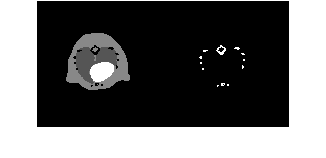

load("axial.mat");
imshowpair(axial(:,:,1),axial(:,:,2),'montage')
title('Density:water of soft tissue, bone');

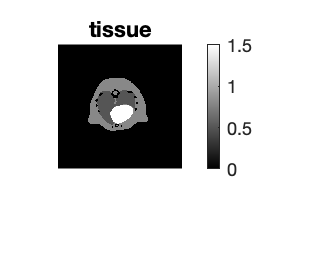


tissue = axial(:,:,1);
tissue = padarray(tissue, [10, 10]);

imshow(tissue, []); 
title('tissue') 
colorbar

`% ================================`

`% Section 2: Generate Projections`

`% ================================`

Run this section, can get projection.mat, which include the two detectors' location of LOR (lines of response).

load 28000_projection.mat, or 100000_projection.mat or new5000projection.mat

% rng('default');
% area_series=randsrc(1,100,[2 1 3;0.8 0.06 0.14]);%Probability of organA is 80%
% 
%ORGAN1_VALUE = 1.5;
%ORGAN2_VALUE = 0.5;
%
%[x_organ1,y_organ1] = find(tissue == ORGAN1_VALUE);
%[x_organ2,y_organ2] = find(tissue == ORGAN2_VALUE);
%[x_organ3,y_organ3] = find(tissue < ORGAN1_VALUE & tissue > ORGAN2_VALUE);
% 
% attribute=zeros(length(area_series),4);
% 
% for i=1:length(area_series)
%     if area_series(i)==1
%         index1=randi(3301);
%         locx=x_organ1(index1);%locx is the index of row, which represent y-axis location
%         locy=y_organ1(index1);
%     elseif area_series(i)==2
%         index2=randi(6770);
%         locx=x_organ2(index2);
%         locy=y_organ2(index2);
%     elseif area_series(i)==3
%         index3=randi(13638);
%         locx=x_organ3(index3);
%         locy=y_organ3(index3);
%     end
%     degree=randi(360);
%     attribute(i,:)=[area_series(i),locy,locx,degree];
% end
% 
% %Lines=zeros(size(attribute,1),3);
% Lines_origin=zeros(size(attribute,1),3);
% for i=1:size(attribute,1)
%     %xsin-ycos-asin+bcos
%     %Lines(i,:)=[sin(deg2rad(attribute(i,4))),-cos(deg2rad(attribute(i,4))),-sin(deg2rad(attribute(i,4)))*attribute(i,2)+cos(deg2rad(attribute(i,4)))*attribute(i,3)];
%     Lines_origin(i,:)=[sin(deg2rad(attribute(i,4))),-cos(deg2rad(attribute(i,4))),-sin(deg2rad(attribute(i,4)))*(attribute(i,2)-200)+cos(deg2rad(attribute(i,4)))*(attribute(i,3)-200)];
% end
% 

`% ================================`

`% Section 2.2: Compute Intersection Points and Define Detector Locations`

`% ================================`

% %points = lineToBorderPoints(Lines,[400,400]);
% 
% 
% x_circle = [];
% y_circle = [];
% r_circle = 150;
% batch_detector=1;%the number of degrees for 1 detector
% 
% for i=1:batch_detector:360
%     x_circle((i-1)/batch_detector+1) = r_circle * cos(i*2*pi/360)+200;
%     y_circle((i-1)/batch_detector+1) = r_circle * sin(i*2*pi/360)+200;
% end
% 
% %struct_detector=struct('degree',keys,'position_x',x_circle-200,'position_y',y_circle-200);
% detector_loc=[x_circle;y_circle]';
% detector_series=1:batch_detector:360;
% projection_loc=zeros(length(area_series),6);
% 
% for i=1:size(attribute,1)
%     syms x real
%     syms y real
%     %assumeAlso(in(x,'integer'));
%     %s=solve(x+y+1==0,x^2+y^2==200^2,x,y)
%     s=solve(Lines_origin(i,1)*x+Lines_origin(i,2)*y+Lines_origin(i,3)==0,x^2+y^2==150^2,x,y);
%     sol_x=double(round(s.x));
%     sol_y=double(round(s.y));
% 
%     %find nearest detector in one direction
%     if  sol_x
%         dist1=norm(attribute(i,2:3)-[200 200]-[sol_x(1) sol_y(1)]);
%         dist2=norm(attribute(i,2:3)-[200 200]-[sol_x(2) sol_y(2)]);
%         if dist1>dist2
%             Intersection_loc_near=[sol_x(2)+200 sol_y(2)+200];
%             Intersection_loc_far=[sol_x(1)+200 sol_y(1)+200];
%         else
%             Intersection_loc_near=[sol_x(1)+200 sol_y(1)+200];
%             Intersection_loc_far=[sol_x(2)+200 sol_y(2)+200];
%         end
% 
%         Euc_distances=sqrt(sum(bsxfun(@minus, detector_loc, Intersection_loc_near).^2,2));%compute Euclidean distances
%         closest_point_index = find(Euc_distances==min(Euc_distances));
%         closest_point_index=closest_point_index(1);
%         %projection_loc(i,:)=[closest_point_index,detector_loc(closest_point_index,1),detector_loc(closest_point_index,2)];
%     
%         Euc_distances2=sqrt(sum(bsxfun(@minus, detector_loc, Intersection_loc_far).^2,2));%compute Euclidean distances
%         closest_point_index2 = find(Euc_distances2==min(Euc_distances2));
%         closest_point_index2=closest_point_index2(1);
%         %projection_loc2(i,:)=[detector_loc(closest_point_index,1),detector_loc(closest_point_index,2),detector_loc(closest_point_index2,1),detector_loc(closest_point_index2,2)];
% 
%         projection_loc(i,:)=[closest_point_index,detector_loc(closest_point_index,1),detector_loc(closest_point_index,2),closest_point_index2,detector_loc(closest_point_index2,1),detector_loc(closest_point_index2,2)];
%     end   
% end


First estimation is to draw a graph of densities of response(LOR), with the help of bresenham line drawing algorithm.

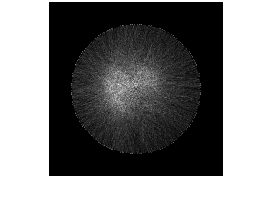

%load('new5000projection.mat')
%load('28000_projection_loc.mat')
routes_x=[];
routes_y=[];
for i=1:size(projection_loc,1)
    %Bresenham line algorithm
    [x_list,y_list]= bresenham(projection_loc(i,2),projection_loc(i,3),projection_loc(i,5),projection_loc(i,6));
    routes_x=[routes_x;x_list];
    routes_y=[routes_y;y_list];
end


Recon=zeros(401,401);
for i=1:size(routes_x,1)
    Recon(routes_y(i)+1,routes_x(i)+1)=Recon(routes_y(i)+1,routes_x(i)+1)+1;
end

figure
fig_recon1=imshow(Recon,[]);

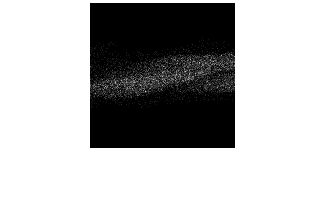

%%%%Convert orginal hit count data to sinogram data
rot_proj=zeros(180,180);
for rot=0:179
for i=1:size(projection_loc,1)
    if projection_loc(i,1)+projection_loc(i,4)==360+2*rot || projection_loc(i,1)+360+projection_loc(i,4)==360+2*rot
        if projection_loc(i,1)>rot && projection_loc(i,1)<rot+180
            rot_proj(projection_loc(i,1)-rot,rot+1)= rot_proj(projection_loc(i,1)-rot,rot+1)+1;
        end
    end
end
end

figure
imshow(rot_proj,[]);
title('Convert LOR to SINO');

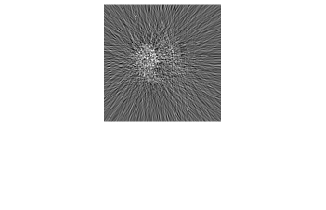


P_num=180;
N=400;
N2=N^2;
delta=1;
theta=0:1:180;
theta=theta(1:180);
P=rot_proj;
M=P_num*length(theta);
P=reshape(P,M,1);

figure
imshow(flip(iradon(rot_proj,delta),2),[]);
title('Reconstruction with default iradon');

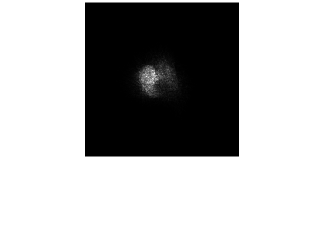


%%Get system matrix
[W_ind,W_dat]=medfuncSystemMatrix(theta,N,P_num,delta);

%%Using MLEM iterative method
F0=ones(N2,1);
irt_num=5;
figure
F=medfuncMLEM(W_ind,W_dat,N,F0,P,irt_num);
F=reshape(F,N,N)';
figure
imshow(flip(imcrop(F,[100 100 200 200]),2),[]);
title('Reconstuction with MLEM');

The error in PET mainly come from Campton Scattering.

N0=Ne^(D*u), D is the distance of LOR(line of response) within tissue. 

e^(D*u) could be calculated with the help of transmisssion scan using CT and external radioactive source.

The method mainly based on the attenuation sinogram, which can be seen as a bridge to add or delete attenuation.

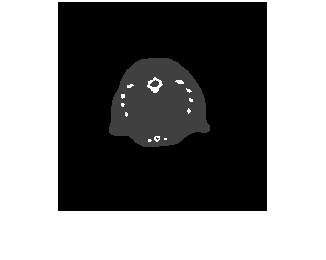

density_water=axial(:,:,1);
density_water = padarray(density_water, [10, 10]);
density_bone=axial(:,:,2);
density_bone = padarray(density_bone, [10, 10]);

MIU_h20=0.02;
MIU_bone=MIU_h20*4;

density_water(density_water~=0)=MIU_h20;
density_bone(density_bone~=0)=MIU_bone;
attencoeff=density_water+density_bone;
imshow(attencoeff,[])

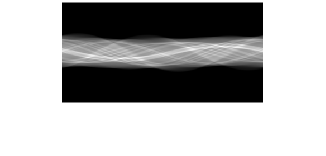


%HU=1000*(miu-miu_h20)/miu_h20. HU_water=0;HU_Bone=1000-3000

density_water=axial(:,:,1);
density_water = padarray(density_water, [10, 10]);
density_bone=axial(:,:,2);
density_bone = padarray(density_bone, [10, 10]);

MIU_h20=0.8;
MIU_bone=MIU_h20*4;

density_water(density_water~=0)=MIU_h20;
density_bone(density_bone~=0)=MIU_bone;
attencoeff=density_water+density_bone;
imshow(attencoeff,[])


%Generate projection data
theta2=0:1:360;
theta2=theta2(1:360);
P_num2=180;
I2=imresize(attencoeff,0.31);
P2=radon(I2,theta2);%ParallelBeamForwardProjection
figure
imshow(P2,[]);

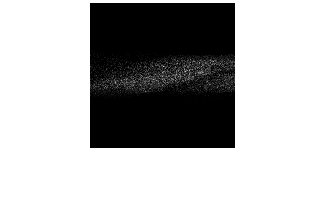

P_180_360=[P2;zeros(1,360)];
P_180_180=P_180_360(:,181:360);
P_180_180=flip(P_180_180,2);

att_LOR_SINO=rot_proj.*P_180_180;
imshow(att_LOR_SINO,[])

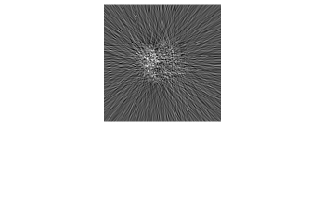

imshow(flip(iradon(att_LOR_SINO,delta),2),[]);

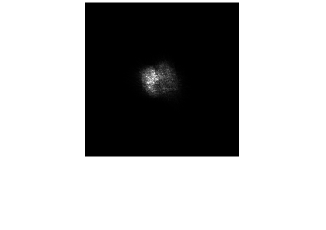


%%获取系统矩阵
[W_ind,W_dat]=medfuncSystemMatrix(theta,N,P_num,delta);
%%利用MLEM算法
P_num=180;
N=400;
N2=N^2;
delta=1;
theta=0:1:180;
theta=theta(1:180);
P=att_LOR_SINO;
M=P_num*length(theta);
P=reshape(P,M,1);
F0=ones(N2,1);
irt_num=5;
figure
F=medfuncMLEM(W_ind,W_dat,N,F0,P,irt_num);
F=reshape(F,N,N)';
figure
imshow(flip(imcrop(F,[100 100 200 200]),2),[]);
title('Reconstuction with MLEM using attenuation projection');

function [x y] = bresenham(x1,y1,x2,y2)
%Usage example:
%[x y]=bresenham(1,1,10,-5);
% plot(x,y,'or');
x1=round(x1); x2=round(x2);
y1=round(y1); y2=round(y2);
dx=abs(x2-x1);
dy=abs(y2-y1);
steep=abs(dy)>abs(dx);
if steep t=dx;dx=dy;dy=t; end

%The main algorithm goes here.
if dy==0 
    q=zeros(dx+1,1);
else
    q=[0;diff(mod([floor(dx/2):-dy:-dy*dx+floor(dx/2)]',dx))>=0];
end

%and ends here.

if steep
    if y1<=y2 y=[y1:y2]'; else y=[y1:-1:y2]'; end
    if x1<=x2 x=x1+cumsum(q);else x=x1-cumsum(q); end
else
    if x1<=x2 x=[x1:x2]'; else x=[x1:-1:x2]'; end
    if y1<=y2 y=y1+cumsum(q);else y=y1-cumsum(q); end
end

end